1) Сохранить данные из файлов в переменные **spectra**, **NameStar**, **lambdaStart **и **lambdaDelta**.

spectra = importdata("spectra.csv");
lambdaStart = importdata("lambda_start.csv");
lambdaDelta = importdata("lambda_delta.csv");
NameStar = importdata('star_names.csv')

NameStar = 7×1 cell array
    {'HD30584'  }
    {'HD10032'  }
    {'HD64191'  }
    {'HD5211'   }
    {'HD56030'  }
    {'HD94028'  }
    {'SAO102986'}


2) Получаем колличемво звёзд(**nStar**) и измерений(**nObs**).

nObs = size(spectra, 1);
nStar = size(spectra, 2);

3) Получаем векторы длин волн **lambda.**

lambdaEnd = lambdaStart + lambdaDelta*(nObs - 1);
lambda = (lambdaStart:lambdaDelta:lambdaEnd)';

4) Находим вектор из минимумов интенсивностей(**sHa**) спектров и их индесы(**idx**). А затем и их длины волн(**lambdaHa**) для всех звёзд.

[sHa, idx] = min(spectra)

sHa = 	1.0e+-12 *

    0.1634    0.0724    0.0314    0.0536    0.0690    0.0980    0.0221


idx =    188   187   188   189   189   191   185


lambdaHa = lambda(idx)

lambdaHa =   656.2000
  656.0600
  656.2000
  656.3400
  656.3400
  656.6200
  655.7800


5) Высчитываем векторы скорости движения звёзд и записываем их в вектор(**speed**).

По формуле: $\vartheta =с\left(\frac{\lambda }{\lambda \iota }-1\right)$, где *с - скорость света.*$\lambda \iota$-истинная длина 

speed = 299792.458 * (lambdaHa/656.28 - 1)

speed =   -36.5445
 -100.4973
  -36.5445
   27.4083
   27.4083
  155.3139
 -228.4029


6-7) График зависимости интенсивности излучения звёзд от их длин волн. Добавление легенды, сетки и подписи. 

grid on
hold on

xlabel('Длина волны, нм')
ylabel(['Интенсивность, эрг/см^2/c/', char(197)])
title('Спекторы звезд в созвездии Льва')
x = linspace(0.1,0.9,nStar) 

x =     0.1000    0.2333    0.3667    0.5000    0.6333    0.7667    0.9000


for i = 1 : nStar
    if speed(i) > 0 
        fgr1 = plot(lambda, spectra(:,i), Color=[1-x(i),x(i),x(i)], LineWidth = 3)
    else
        fgr1 = plot(lambda, spectra(:,i), Color=[1-x(i),x(i),x(i)], LineWidth = 1, LineStyle="--");
    end
end

fgr1 =   Line with properties:

              Color: [0.5000 0.5000 0.5000]
          LineStyle: '-'
          LineWidth: 3
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [630.0200 630.1600 630.3000 630.4400 630.5800 630.7200 630.8600 631 631.1400 631.2800 631.4200 631.5600 631.7000 631.8400 631.9800 632.1200 632.2600 632.4000 632.5400 632.6800 632.8200 632.9600 633.1000 633.2400 633.3800 633.5200 … ]
              YData: [8.9190e-14 8.9810e-14 9.1520e-14 9.3110e-14 9.3550e-14 9.3210e-14 9.2860e-14 9.2470e-14 9.2400e-14 9.1770e-14 8.9590e-14 8.7960e-14 8.7470e-14 8.7220e-14 8.7690e-14 8.8770e-14 8.9910e-14 9.1300e-14 9.2650e-14 9.2530e-14 … ]
              ZData: [1×0 double]

  Show 

fgr1 =   Line with properties:

              Color: [0.3667 0.6333 0.6333]
          LineStyle: '-'
          LineWidth: 3
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [630.0200 630.1600 630.3000 630.4400 630.5800 630.7200 630.8600 631 631.1400 631.2800 631.4200 631.5600 631.7000 631.8400 631.9800 632.1200 632.2600 632.4000 632.5400 632.6800 632.8200 632.9600 633.1000 633.2400 633.3800 633.5200 … ]
              YData: [1.0880e-13 1.0840e-13 1.1040e-13 1.1240e-13 1.1220e-13 1.1360e-13 1.1380e-13 1.1300e-13 1.1240e-13 1.1080e-13 1.0720e-13 1.0760e-13 1.0860e-13 1.0790e-13 1.0860e-13 1.0990e-13 1.1050e-13 1.1270e-13 1.1620e-13 1.1530e-13 … ]
              ZData: [1×0 double]

  Show 

fgr1 =   Line with properties:

              Color: [0.2333 0.7667 0.7667]
          LineStyle: '-'
          LineWidth: 3
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [630.0200 630.1600 630.3000 630.4400 630.5800 630.7200 630.8600 631 631.1400 631.2800 631.4200 631.5600 631.7000 631.8400 631.9800 632.1200 632.2600 632.4000 632.5400 632.6800 632.8200 632.9600 633.1000 633.2400 633.3800 633.5200 … ]
              YData: [1.6250e-13 1.6300e-13 1.6150e-13 1.5860e-13 1.5740e-13 1.5890e-13 1.6110e-13 1.6070e-13 1.5930e-13 1.5820e-13 1.5820e-13 1.6060e-13 1.6120e-13 1.5950e-13 1.5750e-13 1.5610e-13 1.5880e-13 1.6200e-13 1.6150e-13 1.5990e-13 … ]
              ZData: [1×0 double]

  Show 

legend(NameStar)
set(gcf, 'Visible', 'on');

8) В переменую **movaway** записываем звёзды, которые удаляются от земли. 

movaway = NameStar(speed>0);
disp("Звёзды, удаляющиеся от земли:")

Звёзды, удаляющиеся от земли:


disp(movaway')

    {'HD5211'}    {'HD56030'}    {'HD94028'}



9) Сохраняем картинку в PNG.

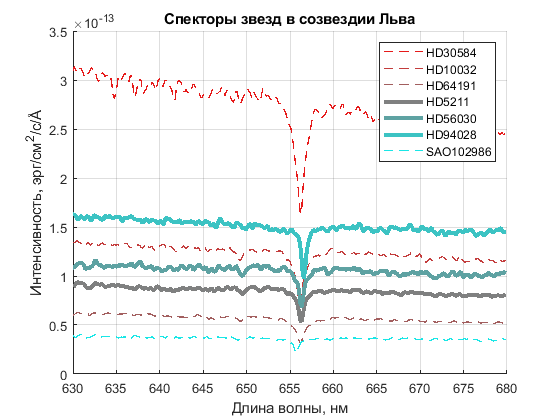

saveas(fgr1,'STARS.png')

10) Усё)))